Now, mortality rate,recovery rate, and infectious contact rate are all modeled with time dependent exponential equations.

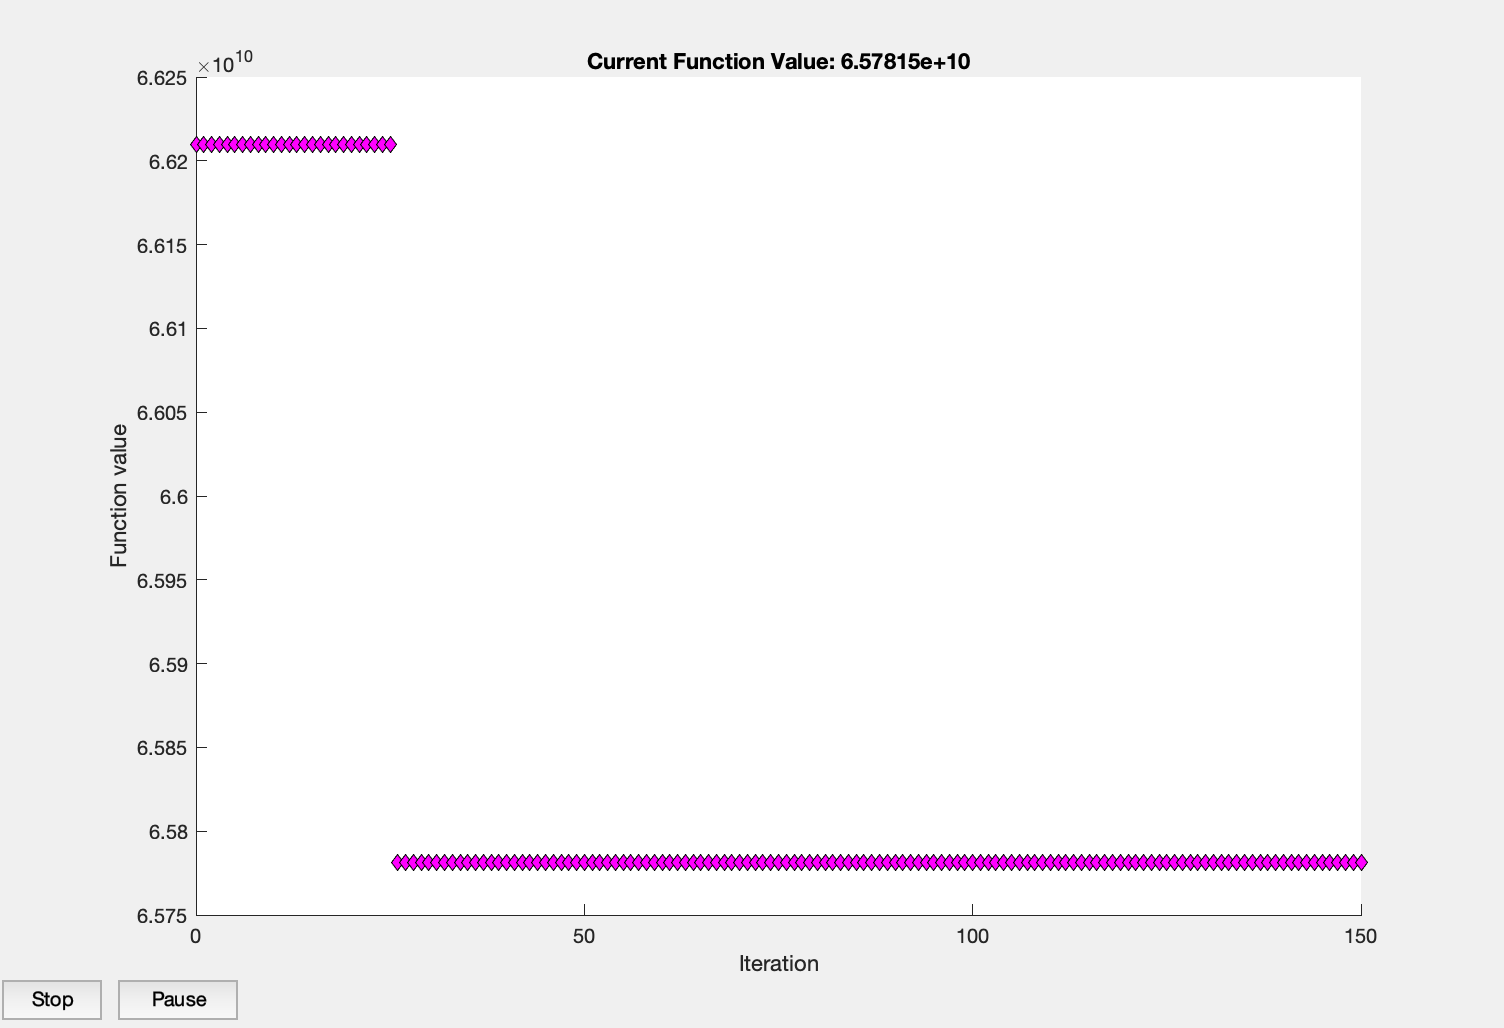

global US_confirmed;
global days_since_jan_21;



M = csvread("US_covid_nums.csv");
[days_since_jan_21,~] = size(M);
US_confirmed = M(:,1);

% guesses for beta gamma and delta constants
b_min = -.1225;
b_0 = .6810;
r = .0122;
gamma_0 = .0148;
gamma_1 = 1.8793;
T_g = 26.1697;
delta_0 = -.2929;
delta_1 = .1983;
T_d = -2.5258;
alpha = .5;
phi = .025;

func_inputs(1) = b_min;
func_inputs(2) = b_0;
func_inputs(3) = r;
func_inputs(4) = gamma_0;
func_inputs(5) = gamma_1;
func_inputs(6) = T_g;
func_inputs(7) = delta_0;
func_inputs(8) = delta_1;
func_inputs(9) = T_d;
func_inputs(10) = alpha;
func_inputs(11) = phi;

maxiter = 1000;
maxfun =  1000;

options = optimset('Display', 'off', 'MaxIter', maxiter, ...
         'MaxFunEvals', maxfun,'PlotFcns',@optimplotfval);
  
for iter = 1:100
         optimum_func_inputs = fminsearch(@err_pred, func_inputs, options);
         func_inputs = optimum_func_inputs;
end

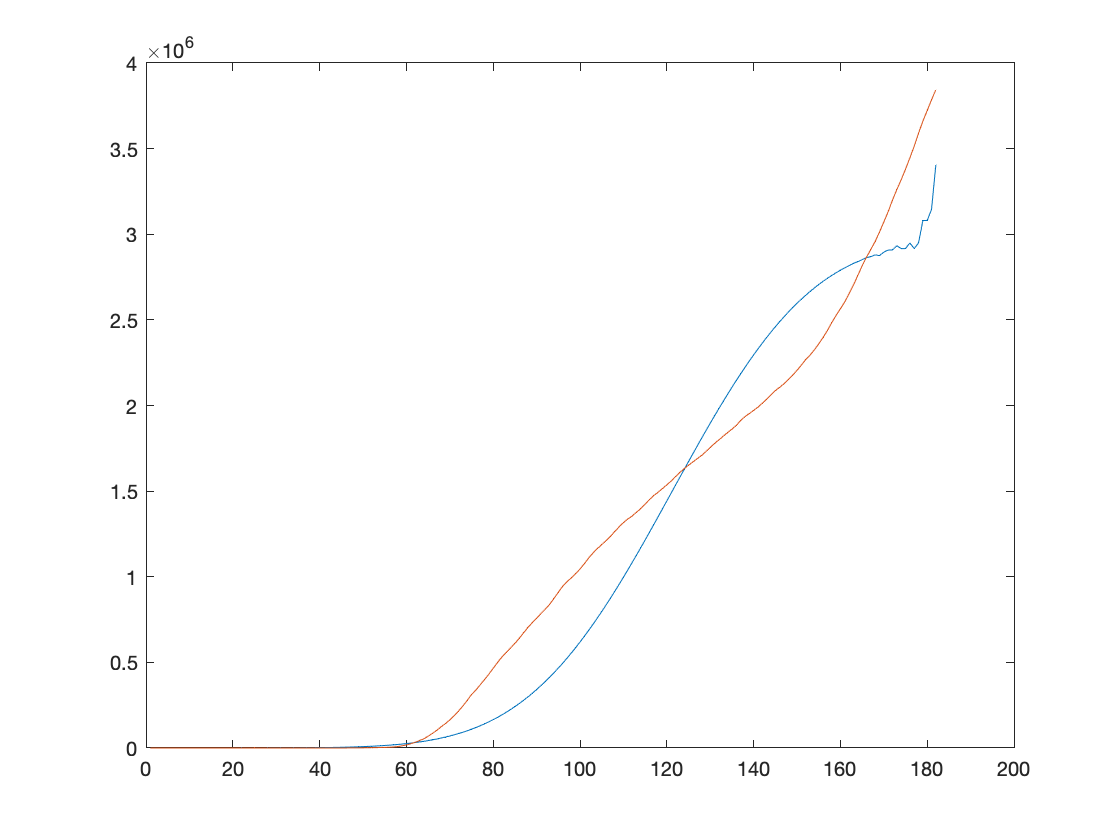



plot_results(optimum_func_inputs, US_confirmed);

function dydt = ode_tspan(t,y,tspan,fbeta,fgamma,fdelta,alpha,phi)

%gotta define the constants in here

N = 328.2e6;
eps = 38.4156/112.846;
pre_infec = 5.1;
sigma = 1/pre_infec;
eta = 0.5;

gamma = interp1(tspan,fgamma,t);
delta = interp1(tspan, fdelta, t);
beta = interp1(tspan,fbeta,t);

S = y(1);
E = y(2);
I = y(3);
A = y(4);
H = y(5);
R = y(6);
D = y(7);
S_R = y(8);
E_R = y(9);
I_R = y(10);
A_R = y(11);
H_R = y(12);
R_R = y(13);
D_R = y(14);

dS = -beta.*(I+eta.*A).*S./N - beta.*((1-0).*I_R+(1-0).*eta.*A_R).*S./N;
dE = beta.*(I+eta.*A).*S./N + beta.*((1-0)*I_R + (1-0)*eta*A_R).*S/N- sigma.*E;
dI = alpha.*sigma.*E-phi.*I-gamma.*I;
dA = (1-alpha).*sigma.*E-gamma.*A;
dH = phi.*I-delta.*H-gamma*H;
dR = gamma*I+gamma*A + gamma*H;
dD = delta*H;

dS_R = -beta.*(1-eps)*(I+eta*A).*S_R./N-beta.*(1-eps)*((1-0).*I_R + (1-0)*eta.*A_R)*S_R/N;
dE_R = beta.*(1-eps)*(I+eta*A).*S_R./N + beta.*(1-eps)*((1-0)*I_R+(1-0)*eta*A_R).*S_R./N - sigma.*E_R;
dI_R = alpha.*sigma.*E_R-phi.*I_R-gamma.*I_R;
dA_R = (1-alpha).*sigma.*E_R-gamma.*A_R;
dH_R = phi.*I_R-delta.*H_R-gamma*H_R;
dR_R = gamma*I_R+gamma*A_R + gamma*H_R;
dD_R = delta*H_R;

dydt = [dS;dE;dI;dA;dH;dR;dD;dS_R;dE_R;dI_R;dA_R;dH_R;dR_R;dD_R];
end
function MSE = err_pred(func_inputs)

global US_confirmed days_since_jan_21;

b_min = func_inputs(1);
b_0 = func_inputs(2);
r = func_inputs(3);
gamma_0 = func_inputs(4);
gamma_1 = func_inputs(5);
T_g = func_inputs(6);
delta_0 = func_inputs(7);
delta_1 = func_inputs(8);
T_d = func_inputs(9);
alpha = func_inputs(10);
phi = func_inputs(11);


tspan = 0:days_since_jan_21-1;
% for beta function, optimize b_min, b_0 and r
fbeta = b_min + (b_0 - b_min)*exp(-r*(tspan+1));

% for gamma function, optimize gamma_0, gamma_1 and T_g
fgamma = gamma_0 + exp(-gamma_1*(tspan+1 +T_g));

% for delta function, optimize delta_0, delta_1 and T_d
fdelta = delta_0 + exp(-delta_1*(tspan+T_d));

N = 328.2e6;
y0 = [N-10,9,1,0,0,0,0,0,0,0,0,0,0,0];
    
[t,y]= ode45(@(t,y)ode_tspan(t,y,tspan, fbeta,fgamma,fdelta,alpha,phi),tspan,y0);
pred_cases = y(:,3) + y(:,5) + y(:,6) + y(:,7) + ...
            y(:,10) + y(:,12) + y(:,13) + y(:,14);

        MSE = sum(sum((pred_cases-US_confirmed).^2))/size(pred_cases,1);
end

function a = plot_results(func_inputs, US_confirmed)
global days_since_jan_21;

b_min = func_inputs(1);
b_0 = func_inputs(2);
r = func_inputs(3);
gamma_0 = func_inputs(4);
gamma_1 = func_inputs(5);
T_g = func_inputs(6);
delta_0 = func_inputs(7);
delta_1 = func_inputs(8);
T_d = func_inputs(9);
alpha = func_inputs(10);
phi = func_inputs(11);


tspan = 0:days_since_jan_21-1;

fbeta = b_min + (b_0 - b_min)*exp(-r*(tspan+1));

% for gamma function, optimize gamma_0, gamma_1 and T_g
fgamma = gamma_0 + exp(-gamma_1*(tspan+1 +T_g));

% for delta function, optimize delta_0, delta_1 and T_d
fdelta = delta_0 + exp(-delta_1*(tspan+T_d));

N = 328.2e6;
y0 = [N-10,9,1,0,0,0,0,0,0,0,0,0,0,0];
    
[t,y]= ode45(@(t,y)ode_tspan(t,y,tspan, fbeta,fgamma,fdelta,alpha,phi),tspan,y0);
pred_cases = y(:,3) + y(:,5) + y(:,6) + y(:,7) + ...
            y(:,10) + y(:,12) + y(:,13) + y(:,14);
        
figure
plot(pred_cases);
hold on;
plot(US_confirmed);
end